clear, clc

## LOAD DATA

MVC = '20';
trial = '2';
path = 'D:\University programming\MATLAB\Module 12\Neuron Parameter Estimation\Processed Data';
name = ['MVC_' MVC '_trial_' trial];
load([path '\' name '.mat'])
clear path, clear name

## INITIAL BOUNDARIES

paramsLabel = {'gNa','gKf','gKs','dSoma','resSoma','threshold',...
    'betaQ','alphaQ','betaN','alphaN','betaH','alphaH'};    % 'betaM','alphaM'
% lb = [10,0.5,8,40,600,1,...
%     0.01,1.5,0.1,1.5,4,0.5];
% ub = [50,5,37.5,130,1200,22,...
%     0.2,22,22,22,22,22];
lb = [10,0.5,4,40,600,12.35,...
    0.01,1.5,0.1,1.5,4,0.5];
ub = [50,4,25,130,1200,22,...
    0.2,22,22,22,22,22];

## CHANGED BOUNDARIES

lb = lb/6;
ub = ub*2;

## CREATE AN INSTANCE FOR ONR NEURON TO OPTIMIZE EACH PARAMETER INDIVIDUALLY

n_parameters = length(paramsLabel);
neuron_num = 1;
spikesExp_vec = spikeTrainsExp(:,neuron_num);
paramLab = {'g_{Na}','g_{Kf}','g_{Ks}','d_{s}','R_{m-s}','V_{th}','\beta_{Q}','\alpha_{Q}','\beta_{N}','\alpha_{N}','\beta_{H}','\alpha_{H}'};

for param_idx = 1:n_parameters
    parLab = paramsLabel(param_idx);
    lb_s = lb(param_idx);
    ub_s = ub(param_idx);
    neuron(param_idx) = NeuronOptimization.Neuron(parLab,lb_s,ub_s,current,spikesExp_vec,tVec);
end

## PLOT THE CONTRIBUTION OF EACH PARAMETER TO ERRORS

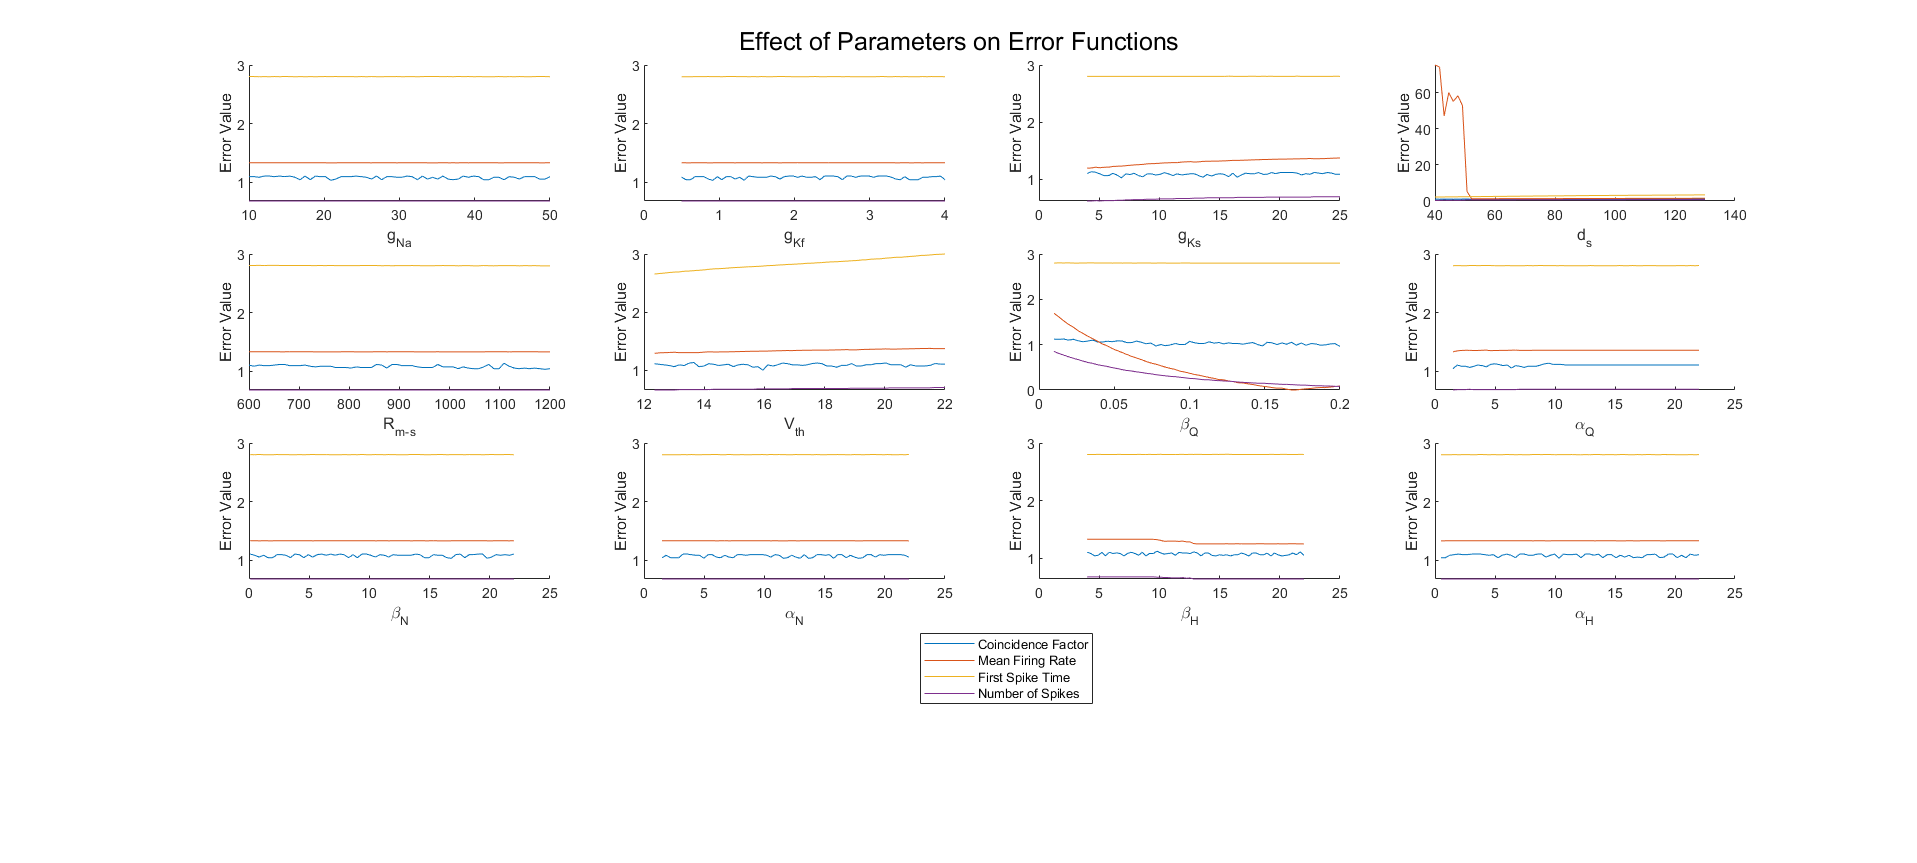

tic
figure, clf
for param_idx = 1:n_parameters
    param_vec = linspace(neuron(param_idx).lb,neuron(param_idx).ub,60);
    Factor = zeros(length(param_vec),4);
    Factor_single = zeros(1,length(param_vec));
    parfor i = 1:length(param_vec)
        factor_single = neuron(param_idx).err_coincidence_factor(param_vec(i));
        Factor_single(i) = factor_single;
        factor = neuron(param_idx).err_moo(param_vec(i));
        Factor(i,:) = factor;
    end
    subplot(4,4,param_idx), hold on
%     plot(param_vec,Factor_single,'k')
    plot(param_vec,Factor(:,1)')
    plot(param_vec,Factor(:,2)')
    plot(param_vec,Factor(:,3)')
    plot(param_vec,Factor(:,4)')
    xlabel(paramLab{param_idx})
    ylabel('Error Value')
end
lg = legend({'Coincidence Factor','Mean Firing Rate','First Spike Time','Number of Spikes'}); % 'factorSingleOp',
set(lg,'Position', [0.5,0.2,0.05,0.05],'units','normalized');
set(gcf,'units','normalized');
set(gcf,'Position',[0, 0, 1, 0.8]);
sgtitle('Effect of Parameters on Error Functions')

toc

Elapsed time is 649.836121 seconds.


## PLOT THE CONTRIBUTION OF EACH PARAMETER TO THE MODEL

tic
figure, clf
for param_idx = 1:n_parameters
    param_vec = linspace(neuron(param_idx).lb,neuron(param_idx).ub,60);
    parfor i = 1:length(param_vec)
        [~,spikeTrainsSim] = neuron(param_idx).simulate_resampling(param_vec(i));
        spikeTimesSim = find(spikeTrainsSim(:,1) == 1);
        meanFiringRateSim(i) = mean(1./diff(spikeTimesSim/2048));
        firstSipkeTime(i) = spikeTimesSim(1)/2048;
    end
    subplot(4,3,param_idx), hold on
    yyaxis left
    plot(param_vec,meanFiringRateSim)
    ylabel('Mean Firing Rate (pps)')
    yyaxis right
    plot(param_vec,firstSipkeTime)
    ylabel('First Time Spike (s)')
    xlabel(paramsLabel{param_idx})
end
set(gcf,'units','normalized');
set(gcf,'Position',[0, 0, 1, 0.8]);
sgtitle(['Parameter Effect Comparison of Neuron ' num2str(neuron_num) ' with' MVC '% MVC in Trial' trial])
toc